## Code for Time Series Data Analysis 

Data are event data with durations in minutes, red and green events.

**License**

% Author: Elisabeth Kugler 2021
% Contact: kugler.elisabeth@gmail.com
%  
% BSD 3-Clause License
% 
% Copyright (c) [2021], [Elisabeth C. Kugler]
% All rights reserved.
% 
% Redistribution and use in source and binary forms, with or without modification, are permitted provided that the following conditions are met:
% 1. Redistributions of source code must retain the above copyright notice, this list of conditions and the following disclaimer.
% 2. Redistributions in binary form must reproduce the above copyright notice, this list of conditions and the following disclaimer in the documentation and/or other materials provided with the distribution.
% 3. Neither the name of the copyright holder nor the names of its contributors may be used to endorse or promote products derived from this software without specific prior written permission.
% THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS" AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT HOLDER OR CONTRIBUTORS BE LIABLE FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY, OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.

## Load data

eventTable = readtable('D:/TimeSeriesEventData.xlsx');
% Create MATLAB datenumbers from the Excel dates
infmt = 'dd/MM/yyyy';
% assign column infos
dates = datetime(eventTable{:,1}, 'InputFormat',infmt);
redEvents = eventTable{:,2};
greenEvents = eventTable{:,3};

## Count number of events and how many are missing

red events

[row, column] = find(redEvents>0);
REs       = [row, column];
cNumREs = length(REs);
missingREs = (365 - cNumREs); % subtract the number of events from days of the year
fprintf('Number of days with red events: %d \n', cNumREs);

Number of days with red events: 125 


 green events

[row, column] = find(greenEvents>0);
GEs       = [row, column];
cNumGEs = length(GEs);
missingGEs = (365 - cNumGEs);
fprintf('Number of days with green events: %d \n', cNumGEs);

Number of days with green events: 69 


## Analyse Mean and Maximum Events

mean values of events

meanREs = mean(eventTable{:,2},"omitnan");
meanGEs = mean(eventTable{:,3},"omitnan");
fprintf('The mean duration of red is: %.2f minutes \nThe mean duration of green is: %.2f minutes \n', meanREs, meanGEs);

The mean duration of red is: 23.10 minutes 
The mean duration of green is: 34.52 minutes 


maximum events

maxREs = max(eventTable{:,2});
maxGEs = max(eventTable{:,3});

if maxREs > maxGEs
    fprintf('The biggest event was red with %.2f minutes \n', maxRES);
else
    fprintf('The biggest event was green with %.2f minutes \n', maxGEs);    
end

The biggest event was green with 90.00 minutes 


## Plot red and green events

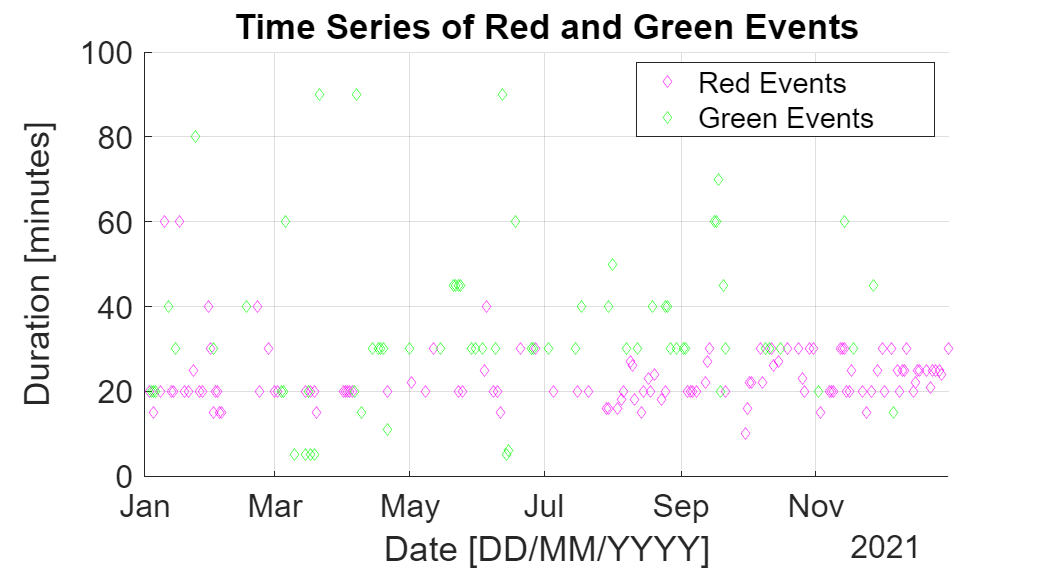

annualEvents = figure('units','normalized','outerposition',[0 0 1 1]);
% Set the font size for the figure
font_size = 24;
set(0, 'DefaultAxesFontSize', font_size);
% Set the figure background to be white
set(gcf,'color','w');
hold on

plot(dates, redEvents, 'dm');
plot(dates, greenEvents, 'dg');

grid on
xlim([min(dates) max(dates)]);

title('Time Series of Red and Green Events')
xlabel('Date [DD/MM/YYYY]')
ylabel('Duration [minutes]')

legend('Red Events','Green Events')

% save image
saveas(annualEvents, 'Events2021.png');

## Examine season subtests: find mean values of red and green events during the 4 seasons

Extract seasons by date > Get the month numbers for dates

monthNum = month(dates(:,1)); 
spring = ismember(monthNum, [1:3]); 
summer = ismember(monthNum, [4:6]); 
autumn = ismember(monthNum, [7:9]); 
winter = ismember(monthNum, [10:12]); 

% create array of seasons to iterate
seasons = [spring summer autumn winter]; % if you'd use ";" instead it's a 4x1 string
seasonNames = {'Spring'; 'Summer'; 'Autumn'; 'Winter'};

% seasonal mean vals REs
meanRESpring = mean(redEvents(spring, :),"omitnan");
meanRESummer = mean(redEvents(summer, :),"omitnan");
meanREAutumn = mean(redEvents(autumn, :),"omitnan");
meanREWinter = mean(redEvents(winter, :),"omitnan");
% add to array
meanREsYear = [meanRESpring, meanRESummer, meanREAutumn, meanREWinter];

% seasonal mean vals GEs
meanGESpring = mean(greenEvents(spring, :),"omitnan");
meanGESummer = mean(greenEvents(summer, :),"omitnan");
meanGEAutumn = mean(greenEvents(autumn, :),"omitnan");
meanGEWinter = mean(greenEvents(winter, :),"omitnan");
% add to array
meanGEsYear = [meanGESpring, meanGESummer, meanGEAutumn, meanGEWinter];

## Make figure with season mean values and plot as scatterplot

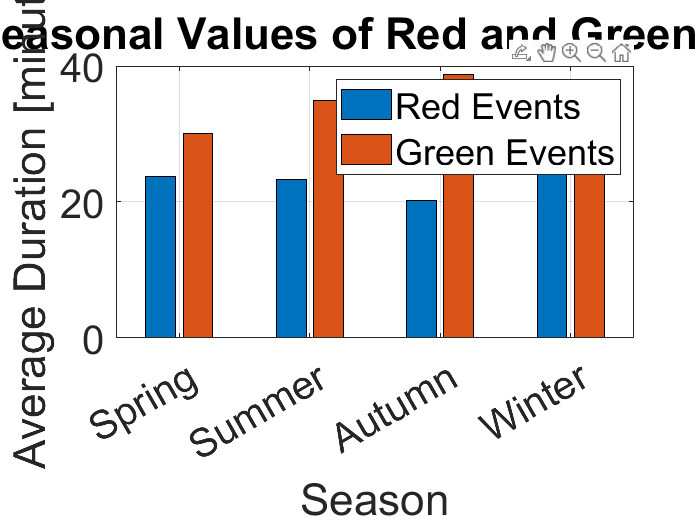

seasonEvents = figure;
bar([meanREsYear;meanGEsYear].');

grid on;
xticklabels(seasonNames);
seasonEvents.WindowState = 'maximized';

title('Average Seasonal Values of Red and Green Events 2021')
xlabel('Season')
ylabel('Average Duration [minutes]')

legend('Red Events','Green Events')

% save image
saveas(seasonEvents, 'SeasonalAvgs.png');

## Subset Test - April 2021 data

monthIdxApril = ismember(monthNum, [4]); 
% Extract your data for these months
% April2021Dates = find(dates>='2021-04-01' & dates<='2021-04-30'); %
% 91-120
April2021Dates = dates(monthIdxApril, :);
April2021RE = redEvents(monthIdxApril, :);
April2021GE = greenEvents(monthIdxApril, :);

## Plot red and green events in April 2021

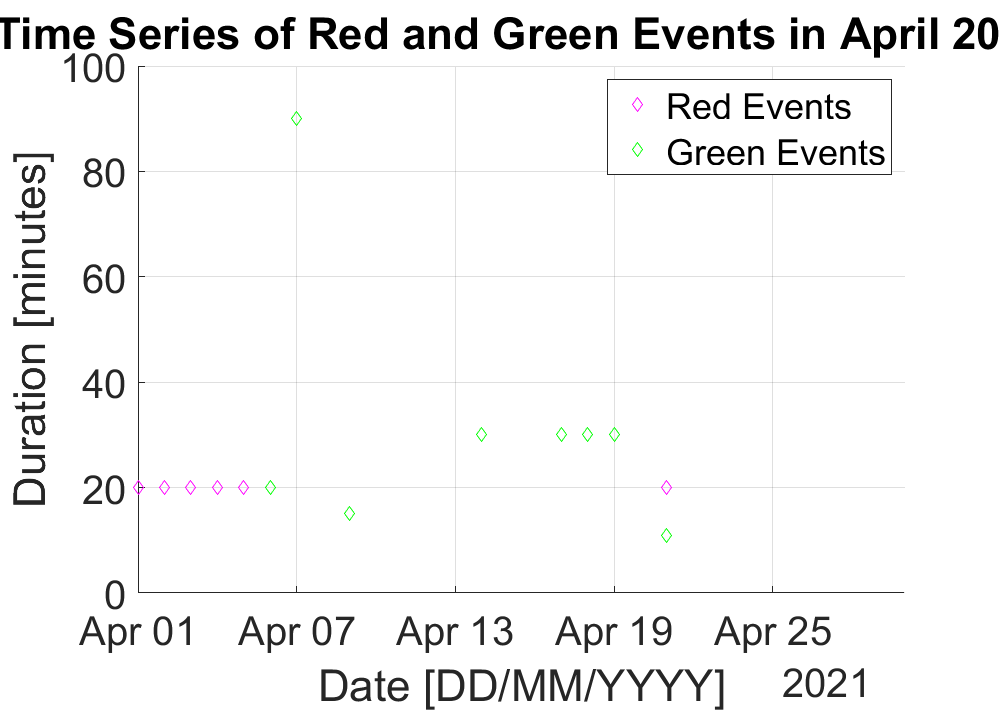

aprilEvents = figure('units','normalized','outerposition',[0 0 1 1]);
% Set the font size for the figure
font_size = 24;
set(0, 'DefaultAxesFontSize', font_size);
% Set the figure background to be white
set(gcf,'color','w');
hold on

plot(April2021Dates, April2021RE, 'dm');
plot(April2021Dates, April2021GE, 'dg');

grid on
xlim([min(April2021Dates) max(April2021Dates)]);

title('Time Series of Red and Green Events in April 2021')
xlabel('Date [DD/MM/YYYY]')
ylabel('Duration [minutes]')

legend('Red Events','Green Events')

% save image
saveas(aprilEvents, 'EventsApril2021.png');

## Examination of filling in missing data

open question: how to check whether interpolation even makes sense if there aren't that many events? (e.g. 70 green events)

% call function from different folder
addpath('./Inpaint_nans/Inpaint_nans/');
% inpaint_nans from: https://uk.mathworks.com/matlabcentral/fileexchange/4551-inpaint_nans
filled_redEvents = inpaint_nans(redEvents,5);
filled_greenEvents = inpaint_nans(greenEvents,5); % green events trail off Dec 2021, similar to interp with interp1 'spline'

% TODO look at inpaint_nans with having to be above 0 - because events
% cannot be negative

% % Looked at interpolation - but for these data inpaint_nans seems
% appropriate... maybe because there are too many missing?
% Interpolate to 1-day
%xq = (min(dates):1:max(dates));
% %TODO interp with NANs https://stackoverflow.com/questions/20582106/how-to-use-interp1-with-nan-values
% % change NaNs to 0 so they'll get interpolated
% FilledredEvents = fillmissing(redEvents, 'constant', 0);
% FilledgreenEvents = fillmissing(greenEvents, 'constant', 0);
% % interpolate with 'linear' - looked at some others
%interpREs = interp1(dates, filled_redEvents, xq, 'linear');
%interpGEs = interp1(dates, filled_greenEvents, xq, 'linear');

## Make a figure with Interpolated Data

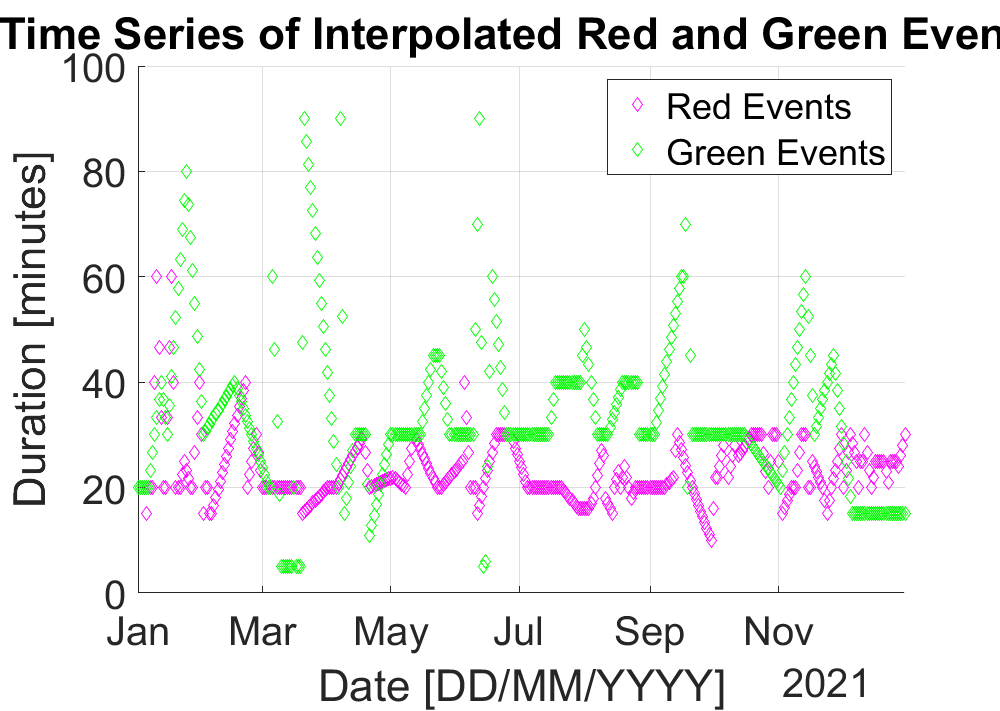

InterpolAnnualEvents = figure('units','normalized','outerposition',[0 0 1 1]);
% Set the font size for the figure
font_size = 24;
set(0, 'DefaultAxesFontSize', font_size);
% Set the figure background to be white
set(gcf,'color','w');
hold on

plot(dates, filled_redEvents, 'dm');
plot(dates, filled_greenEvents, 'dg');

grid on
xlim([min(dates) max(dates)]);

title('Time Series of Interpolated Red and Green Events')
xlabel('Date [DD/MM/YYYY]')
ylabel('Duration [minutes]')

legend('Red Events','Green Events')

% save image
saveas(InterpolAnnualEvents, 'InterpolEvents2021_method5.png');

## Smoothen Data

filters need Signal Processing Toolbox to be installed [https://uk.mathworks.com/help/signal/examples/signal-smoothing.html](https://uk.mathworks.com/help/signal/examples/signal-smoothing.html) Median Filter:

filled_redEventsMedFilt = medfilt1(filled_redEvents,7);
filled_redEventsMedSmooth = smoothdata(filled_redEvents,7);
% Savitzky-Golay filtering:
% https://uk.mathworks.com/help/signal/ref/sgolayfilt.html
filled_redEventsMedSGolay = sgolayfilt(filled_redEvents,3,7); % order, framelength

% filter green events
filled_greenEventsMedFilt = medfilt1(filled_greenEvents,7);
filled_greenEventsMedSmooth = smoothdata(filled_greenEvents,7);
filled_greenEventsMedSGolay = sgolayfilt(filled_greenEvents,3,7); % order, framelength

## Make Figure with Smoothened/Filtered Red Data

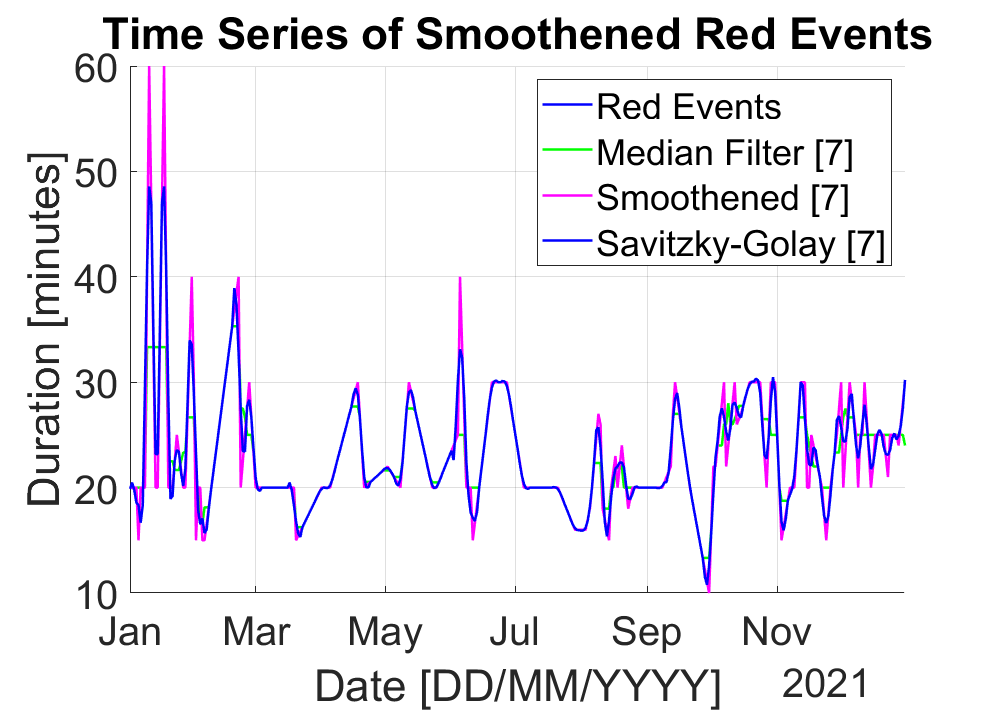

SmoothenedR = figure('units','normalized','outerposition',[0 0 1 1]);
% Set the font size for the figure
font_size = 24;
set(0, 'DefaultAxesFontSize', font_size);
% Set the figure background to be white
set(gcf,'color','w');
hold on

p1 = plot(dates, filled_redEvents, '-b');
p2 = plot(dates, filled_redEventsMedFilt, '-g');
p3 = plot(dates, filled_redEventsMedSmooth, '-m');
p4 = plot(dates, filled_redEventsMedSGolay, '-b');
p1.LineWidth = 1.5;
p2.LineWidth = 1.5;
p3.LineWidth = 1.5;
p4.LineWidth = 1.5;

grid on
xlim([min(dates) max(dates)]);

title('Time Series of Smoothened Red Events')
xlabel('Date [DD/MM/YYYY]')
ylabel('Duration [minutes]')

legend('Red Events','Median Filter [7]', 'Smoothened [7]', 'Savitzky-Golay [7]')

% save image
saveas(SmoothenedR, 'SmoothenedRedEvents2021.png');

## Make Figure with Smoothened/Filtered Green Data

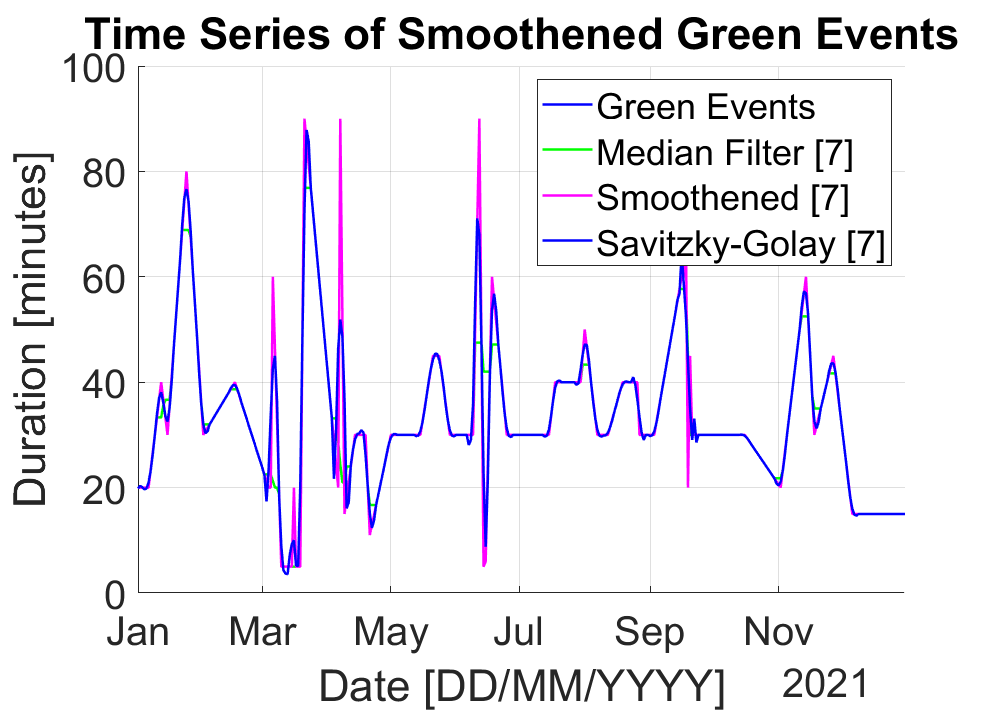

SmoothenedG = figure('units','normalized','outerposition',[0 0 1 1]);
% Set the font size for the figure
font_size = 24;
set(0, 'DefaultAxesFontSize', font_size);
% Set the figure background to be white
set(gcf,'color','w');
hold on

p1 = plot(dates, filled_greenEvents, '-b');
p2 = plot(dates, filled_greenEventsMedFilt, '-g');
p3 = plot(dates, filled_greenEventsMedSmooth, '-m');
p4 = plot(dates, filled_greenEventsMedSGolay, '-b');
p1.LineWidth = 1.5;
p2.LineWidth = 1.5;
p3.LineWidth = 1.5;
p4.LineWidth = 1.5;

grid on
xlim([min(dates) max(dates)]);

title('Time Series of Smoothened Green Events')
xlabel('Date [DD/MM/YYYY]')
ylabel('Duration [minutes]')

legend('Green Events','Median Filter [7]', 'Smoothened [7]', 'Savitzky-Golay [7]')

% save image
saveas(SmoothenedG, 'SmoothenedGreenEvents2021.png');

## Modelling Future Values

[https://uk.mathworks.com/matlabcentral/fileexchange/74211-11-classical-time-series-forecasting-methods-in-matlab](https://uk.mathworks.com/matlabcentral/fileexchange/74211-11-classical-time-series-forecasting-methods-in-matlab) 

[https://uk.mathworks.com/help/ident/ug/time-series-prediction-and-forecasting-for-prognosis.html#d123e69236](https://uk.mathworks.com/help/ident/ug/time-series-prediction-and-forecasting-for-prognosis.html#d123e69236) 

1) use Jan-Jun 2021 to model 

2) Jul-Dec 2021 to test which model is the appropriate one 

3) then use Jan-Dec with the appropriate model to predict 2022 data